plecs

   USAGE: PLECS('CMD','PARAMETER1','PARAMETER2',...)
     Known commands are: get, set, version, hostid, thermal, scope, checkout


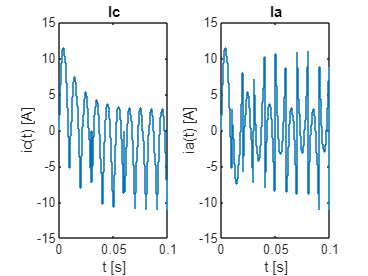

fg = 50; %[Hz] Frecuencia red
Tg = 1 / fg; %[s]
ft = 20 * fg; %[Hz] Frecuencia triangular
Tt = 1 / ft; %[s]
m = 1; %[pu] |V*|
Ts = Tt / 2; %[s] Período de muestro
Va = 100 * sqrt(2); %[V] Tensión red
Vcc = Va / sqrt(2); %[V] Tensión bus DC
C = 1e-3; %[F] Condensador SM
L = 1e-3; %[H] Inductancia serie
R = 1e-3; %[Ohm] Resistencia serie
Z = 10; %[Ohm] Carga

out = sim("HB", 0.1);

% Corriente del condensador
subplot(1, 2, 1)
plot(out.ic)
title("Ic")
xlabel("t [s]")
ylabel("ic(t) [A]")

% Corriente de la carga
subplot(1, 2, 2)
plot(out.ia)
title("Ia")
xlabel("t [s]")
ylabel("ia(t) [A]")

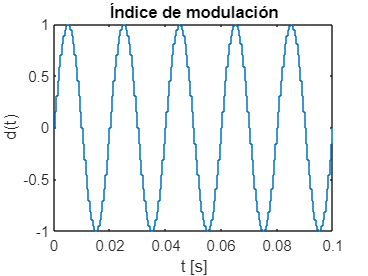


% Índice de modulación
clf
plot(out.d)
title("Índice de modulación")
xlabel("t [s]")
ylabel("d(t)")

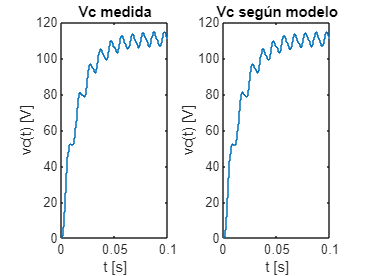


% Tensión del condensador
subplot(1, 2, 1)
plot(out.vc)
title("Vc medida")
xlabel("t [s]")
ylabel("vc(t) [V]")

% Cálculo de Vc según modelo dinámico discreto
ic = out.ic.Data;
vc = out.vc.Data;
t = out.ia.Time;
ia = out.ia.Data;
d = out.d.Data;
N = length(ia); % Horizonte de predicción
v = zeros(N, 1);
for k = 1 : N - 1
    v(k + 1) = v(k) + Ts / C * ia(k) * d(k);
end

subplot(1, 2, 2)
stairs(t, v)
title("Vc según modelo")
xlabel("t [s]")
ylabel("vc(t) [V]")


% Duda:
v % -> Es cero en el primer y segundo instante

v =          0
         0
    0.1724
    0.8403
    2.2638
    4.6081
    7.9251
   12.1505
   17.1153
   22.5695


vc% -> Es cero solo en el primer instante

vc =          0
    0.0773
    0.4753
    1.4951
    3.3582
    6.1794
    9.9546
   14.5662
   19.8014
   25.3816



% Error total:
sum(abs(vc - v))

ans = 112.1794